# **Отчёт по лабораторной работе 1.**

# **Выполнил Барыбин С.М.**

**Задание 1**

Разработал функции в матлаб, реализующие необходимые методы.

**Задание 2**

Не помня номер компьютера в компьютерном классе, выполнил работу в соответствии с номером по списку. Таким образом тестовая функция:


$$f\left(x\right)=x^4 +x^2 +x+1,x\text{ }\epsilon \text{ }\left\lbrace -1;0\right\rbrace$$


**Задание 3**

Требуется построить график и для всех методов изучить скорость работы. Сравнить методы друг с другом. Объяснить результаты.

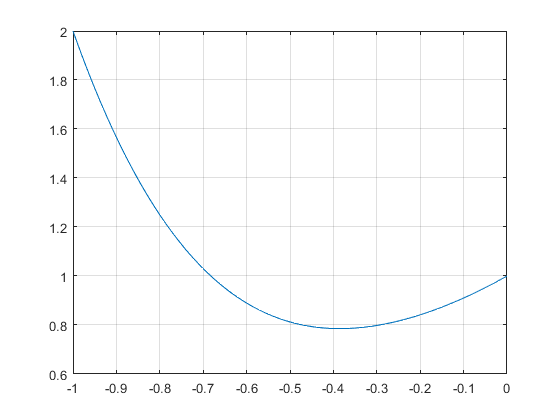

clc
clear
x = -1:.01:0;
y = x.^4 + x.^2 + x + 1;
plot(x,y);
grid on

f = @(x)x^4 + x^2 + x + 1; 

 График построен.

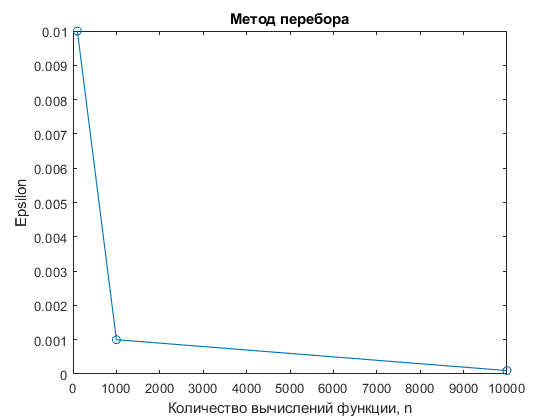

format long

eps = [0.01 0.001 0.0001 0.0001]; % изменил последнюю точность
a = -1;
b = 0;
for i = 1:length(eps)
    [fmin(i), xmin(i), n(i)] = perebor(f, a, b, eps(i));
end
% Строим график eps против n
plot(n, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод перебора');

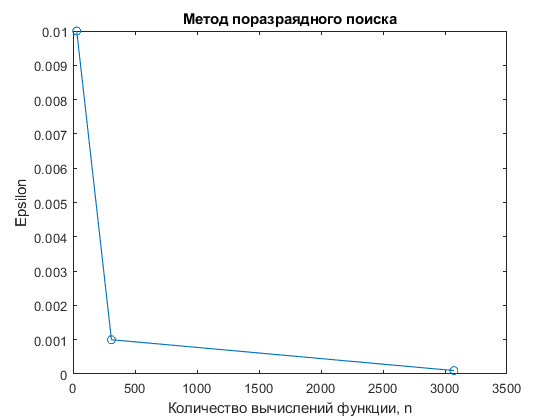

format long

eps = [0.01 0.001 0.0001]; % изменил последнюю точность
a = -1;
b = 0;
n = 1:length(eps);
for i = 1:length(eps)
    [fmin(i), xmin(i), n(i)] = porazr(f, a, b, eps(i));
end
% Строим график eps против n
plot(n, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод поразраядного поиска');

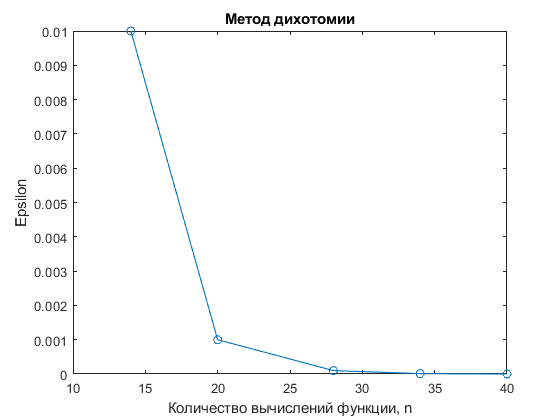


format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n1 = 1:length(eps);
for i = 1:length(eps)
    [fmin1(i), xmin1(i), n1(i)] = dihotomy(f, a, b, eps(i));
end
% Строим график eps против n
plot(n1, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод дихотомии');

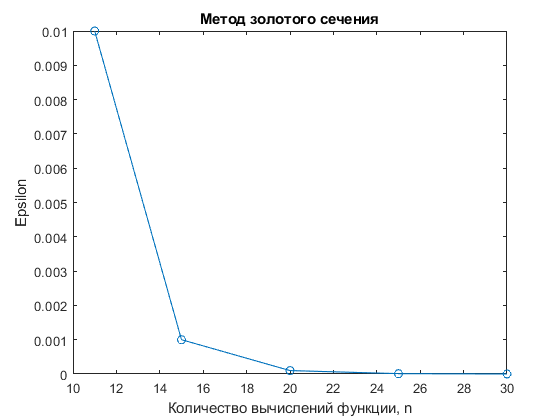

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n2 = 1:length(eps);
for i = 1:length(eps)
    [fmin2(i), xmin2(i), n2(i)] = gold(f, a, b, eps(i));
end
% Строим график eps против n
plot(n2, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод золотого сечения');

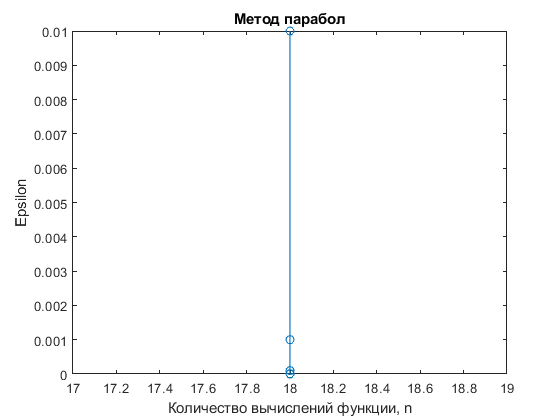

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n3 = 1:length(eps);
for i = 1:length(eps)
    [fmin3(i), xmin3(i), n3(i)] = parabols(f, a, b, eps(i));
end
% Строим график eps против n
plot(n3, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод парабол');

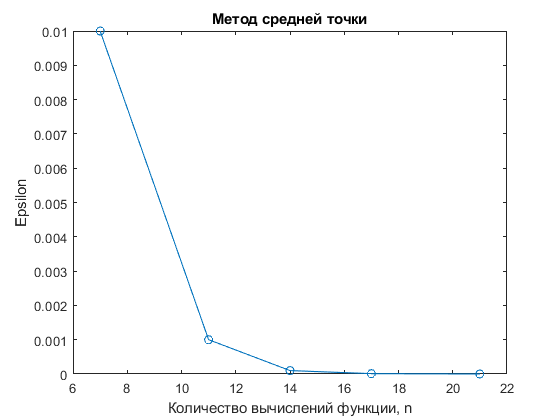

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n4 = 1:length(eps);
for i = 1:length(eps)
    [fmin4(i), xmin4(i), n4(i)] = ave_point(f, a, b, eps(i));
end
% Строим график eps против n
plot(n4, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод средней точки');

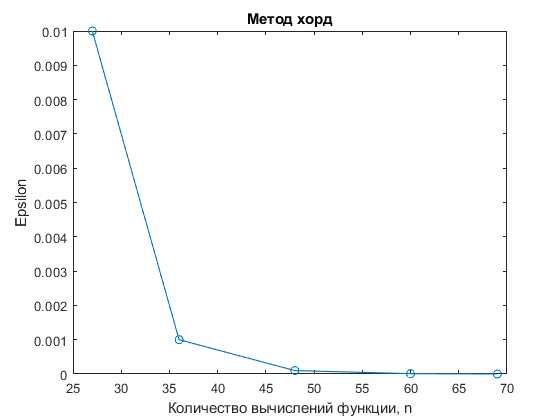

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n5 = 1:length(eps);
for i = 1:length(eps)
    [fmin5(i), xmin5(i), n5(i)] = hords(f, a, b, eps(i));
end
% Строим график eps против n
plot(n5, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод хорд');

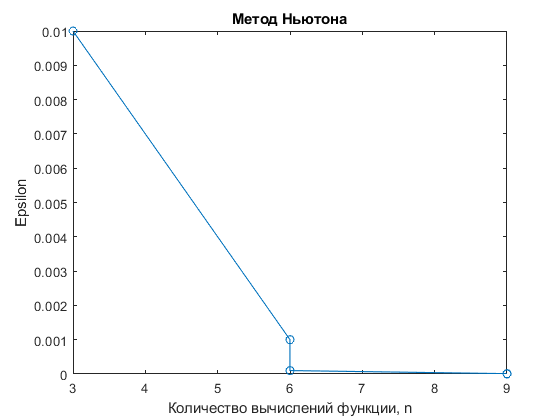

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n6 = 1:length(eps);
for i = 1:length(eps)
    [fmin6(i), xmin6(i), n6(i)] = newton(f, a, b,-0.35, eps(i));
end
% Строим график eps против n
plot(n6, eps, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод Ньютона');
hold off

Все методы реализованы, проведена минимизация функции. Для наглядности построим график зависимости eps(n) для всех методов, кроме поразрядного поиска и перебора

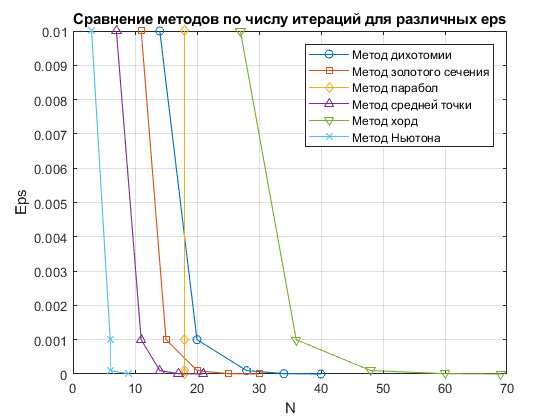


ylim = [10^-2 10^-6];

plot(n1, eps, '-o'); % Линия с маркерами для метода дихотомии
hold on
plot(n2, eps, '-s'); % Линия с квадратными маркерами для метода золотого сечения
plot(n3, eps, '-d'); % Линия с ромбовидными маркерами для метода парабол
plot(n4, eps, '-^'); % Линия с треугольными маркерами для метода средней точки
plot(n5, eps, '-v'); % Линия с перевернутыми треугольниками для метода хорд
plot(n6, eps, '-x'); % Линия с крестиками для метода Ньютона
hold off
grid on
ylabel('Eps');
xlabel('N');
legend({'Метод дихотомии', 'Метод золотого сечения', 'Метод парабол', 'Метод средней точки', 'Метод хорд', 'Метод Ньютона'});
title('Сравнение методов по числу итераций для различных eps');

disp([fmin1(5),xmin1(5);fmin2(5),xmin2(5);fmin3(5),xmin3(5);fmin4(5),xmin4(5);fmin5(5),xmin5(5);fmin6(5),xmin6(5)]);

   0.785195253147152  -0.385458583932400
   0.785195253147141  -0.385458462063981
   0.785195253147138  -0.385458497423842
   0.785195253147140  -0.385458469390869
   0.785195253147269  -0.385458235525568
   0.785195253147138  -0.385458498540796



Для проверки вывел последние значения, полученные различными методами, значения до 6 знаков после запятой. Метод хорд требует больше всего вычислений функции, так как на каждой итерации рассчитывается 3 значения f'(x). Метод Ньютона довольно быстро сходится, взято удачное начальное приближение точки минимума, также функция выпуклая и дважды диффернцируемая, поэтому очерёдное приближение оказывается достаточно близким к $x^\ast $.

**4. В методах, использующих производную оптимизируемой функции, использовать её разностный аналог. Сравнить результаты п.3**

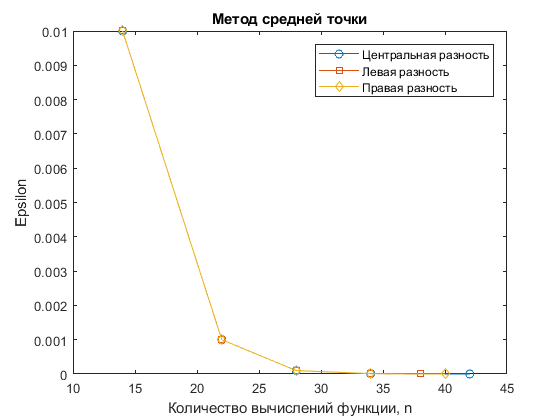

format long

eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n4_c = 1:length(eps);
n4_l = 1:length(eps);
n4_r = 1:length(eps);
for i = 1:length(eps)
    [fmin4(i), xmin4(i), n4c(i)] = ave_point_centr(f, a, b, eps(i));
end
for i = 1:length(eps)
    [fmin4(i), xmin4(i), n4l(i)] = ave_point_left(f, a, b, eps(i));
end
for i = 1:length(eps)
    [fmin4(i), xmin4(i), n4r(i)] = ave_pointright(f, a, b, eps(i));
end
% Строим график eps против n
plot(n4c, eps, '-o'); % '-o' добавляет маркеры для удобства
hold on
plot(n4l, eps, '-s'); % '-o' добавляет маркеры для удобства
plot(n4r, eps, '-d'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод средней точки');
legend({'Центральная разность','Левая разность','Правая разность'})
hold off

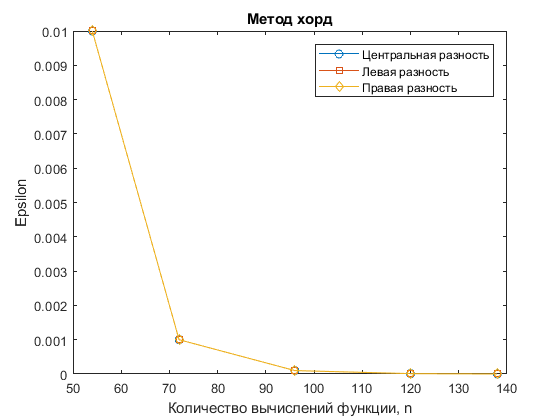


eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n5c = 1:length(eps);
n5l = 1:length(eps);
n5r = 1:length(eps);
for i = 1:length(eps)
    [fmin5(i), xmin5(i), n5c(i)] = hords_central(f, a, b, eps(i));
end
for i = 1:length(eps)
    [fmin5(i), xmin5(i), n5l(i)] = hords_left(f, a, b, eps(i));
end
for i = 1:length(eps)
    [fmin5(i), xmin5(i), n5r(i)] = hords_rigth(f, a, b, eps(i));
end
% Строим график eps против n
plot(n5c, eps, '-o'); % '-o' добавляет маркеры для удобства
hold on
plot(n5l, eps, '-s'); % '-o' добавляет маркеры для удобства
plot(n5r, eps, '-d'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод хорд');
legend({'Центральная разность','Левая разность','Правая разность'})
hold off

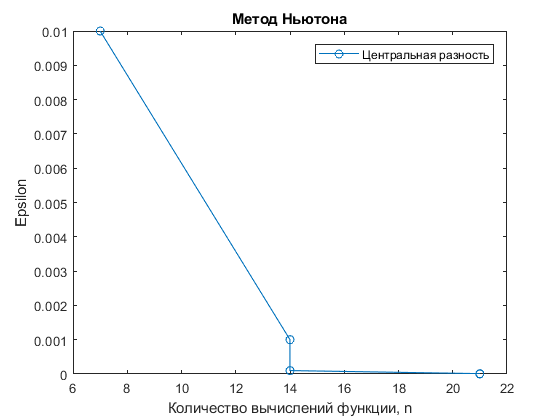


eps = [0.01 0.001 0.0001 0.00001 0.000001]; % изменил последнюю точность
a = -1;
b = 0;
n6c = 1:length(eps);
for i = 1:length(eps)
    [fmin6(i), xmin6(i), n6c(i)] = newton_centr(f, a, b,-0.35, eps(i));
end
% Строим график eps против n
plot(n6c, eps, '-o'); % '-o' добавляет маркеры для удобства
hold on
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод Ньютона');
legend({'Центральная разность'})
hold off

Реализовал данные методы, количество вычислений функции увеличлось, так как для 1-ой производной требуется 2 значения, а для 2-ой производной 3 значения. Получается, что вычичсление аналитической производной позволяет увеличить скорость работы метода.

**5. С помощью метода Ньютона, используя аналитические производные и их аналитические значения, решить задачу оптимизации функции:**


$$f\left(x\right)=x\cdot \mathrm{arctg}\left(x\right)-\frac{1}{2}\cdot \mathrm{ln}\left(x\right)$$


Для нескольких вариантов начального приближения и убедиться, что метод может расходиться, найти диапазон начальных приближений.

Сначала построим график функции:

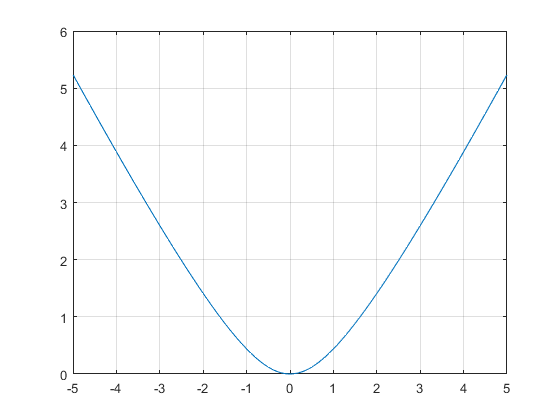

clc
clear
clf
x = -5:.1:5;
y = x.*atan(x) - 0.5*log(1+x.^2);
plot(x,y)
grid on
hold off

Далее вызовем функцию, реализующую метод Ньютона, для различных начальных приближений из интервала [-3,3], после чего сделаем найдём дипазон начальных приближений, при которых метод Ньютона сходится.

x0 = -1.5:.1:1.5;
f = @(x)x*atan(x)-0.5*log(1+x^2);
n = 1:length(x0);
nc = 1:length(x0);
xmin = 1:length(x0);
fmin = 1:length(x0);
xminc = 1:length(x0);
fminc = 1:length(x0);
for i=1:length(x0)
   [xmin(i),fmin(i),n(i)] = newton(f,-3,3,x0(i),0.0001);
   [xminc(i),fminc(i),nc(i)] = newton_centr(f,-3,3,x0(i),0.0001);
end
disp('Аналитическая производная');

Аналитическая производная


disp([xmin(:),fmin(:)])

   1.0e-04 *

                 NaN                 NaN
                 NaN                 NaN
   0.000003442754761   0.262402544231946
   0.000000000000000   0.000000075990038
   0.000000002090867  -0.006466633222756
   0.000000000000003  -0.000007963096044
   0.000034424771980   0.829756253605957
   0.000000100070388   0.044737095973787
   0.000000000116640   0.001527347699244
   0.000000000000042   0.000029044656946
   0.000000000000000   0.000000251314737
   0.000011160889164  -0.472459292813615
   0.000000068044287  -0.036890184918585
   0.000000000048775  -0.000987674215148
   0.000000000000000  -0.000001963530615
                   0                   0
   0.000000000000000   0.000001963530615
   0.000000000048775   0.000987674215148
   0.000000068044287   0.036890184918585
   0.000011160889164   0.472459292813615
   0.000000000000000  -0.000000251314737
   0.000000000000042  -0.000029044656946
   0.000000000116640  -0.001527347699244
   0.000000100070388  -0.044737095973787
  

disp('Численная производная');

Численная производная


disp([xminc(:),fminc(:)]);

   1.0e-04 *

                 NaN                 Inf
                 NaN                -Inf
   0.000002677883429   0.231425274966890
   0.000000000001587   0.000195131790204
   0.000000001089844  -0.004669136130578
   0.000000000102917   0.001431984415386
   0.000037997993852   0.871756775372781
   0.000000019133147   0.019561883908732
   0.000000002450527   0.007001356828748
   0.000000000005682  -0.000335158315613
   0.000000000004332   0.000296196860582
   0.000008669097500  -0.416391571172389
   0.000000138309290  -0.052594548529440
   0.000000006616080  -0.011503481668739
   0.000000000000974   0.000144355199973
                   0                   0
   0.000000000000974  -0.000144355199973
   0.000000006616080   0.011503481668739
   0.000000138309290   0.052594548529440
   0.000008669097500   0.416391571172389
   0.000000000004332  -0.000296196860582
   0.000000000005682   0.000335158315613
   0.000000002450527  -0.007001356828748
   0.000000019133147  -0.019561883908732
  

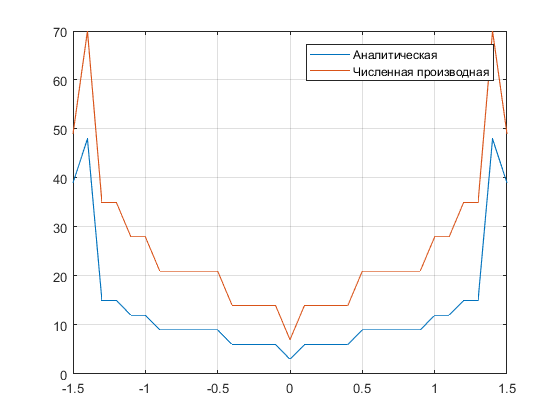

plot(x0,n)
hold on
plot(x0,nc)
grid on
legend({'Аналитическая','Численная производная'})
hold off

Получается, метод Ньютона для этой функции будет сходится при $x\in \left\lbrace -1\ldotp 48,1\ldotp 48\right\rbrace$

Далее рашим эту же задачу методами Ньютона-Рафсона и Марквардта.

format long
x0 = -5:.2:5;
f = @(x)x*atan(x)-0.5*log(1+x^2);
n = 1:length(x0);
nc = 1:length(x0);
xmin = 1:length(x0);
fmin = 1:length(x0);
xminc = 1:length(x0);
fminc = 1:length(x0);
for i=1:length(x0)
   [xmin(i),fmin(i),n(i)] = newt_rafs(f,-3,3,x0(i),0.0001);
   [xminc(i),fminc(i),nc(i)] = markwardt(f,-3,3,x0(i),0.0001);
end
disp('Метод Ньютона-Рафсона');

Метод Ньютона-Рафсона


disp([xmin(:),fmin(:)])

   1.0e-04 *

                 NaN                 NaN
                 NaN                 NaN
                 NaN                 NaN
                 NaN                 NaN
                 NaN                 NaN
                 NaN                 NaN
                 NaN                 NaN
                 NaN                 NaN
                 NaN                 NaN
   0.000000000001160   0.000152282737522
   0.000000000000001   0.000004589495822
   0.000000000000002  -0.000005511619421
   0.000000000619635   0.003520327680126
   0.000000000000003  -0.000007607296188
   0.000000000000000  -0.000000715116977
   0.000000319111567   0.079888868658728
   0.000000000000351   0.000083780418705
   0.000008404359669  -0.409984381940787
   0.000017937521073   0.598957779540665
   0.000001340820697  -0.163757179809584
   0.000000000000000   0.000001083083479
   0.000000000000012   0.000015695750543
   0.000000000000000   0.000000939599378
   0.000005016204473  -0.316739781957773
  

disp('Метод Марквардта');

Метод Марквардта


disp([xminc(:),fminc(:)]);

   1.0e-04 *

   0.000026037259721  -0.721626769781378
   0.000015969952601  -0.565154007504121
   0.000003359878769  -0.259224951320504
   0.000000676361905   0.116306655440065
   0.000009629149336   0.438842781383447
   0.000016963237291   0.582464373177359
   0.000009483353333   0.435507826247910
   0.000000252512138  -0.071065060096095
   0.000043733710665  -0.935240190842886
   0.000000163863846  -0.057247505864201
   0.000000607933149  -0.110266327499457
   0.000001912360483  -0.195568938392968
   0.000006001721954  -0.346459866507122
   0.000020052642570  -0.633287337371460
   0.000000048082113  -0.031010357259697
   0.000000233360958  -0.068317048757536
   0.000001131181868  -0.150411559957042
   0.000005371444781  -0.327763475159345
   0.000024602841286  -0.701467623004286
   0.000000101834942  -0.045129799936347
   0.000000574586435  -0.107199480863251
   0.000002665793894  -0.230902312424973
   0.000008797150217  -0.419455604803061
   0.000016309616021  -0.571132489522975
  

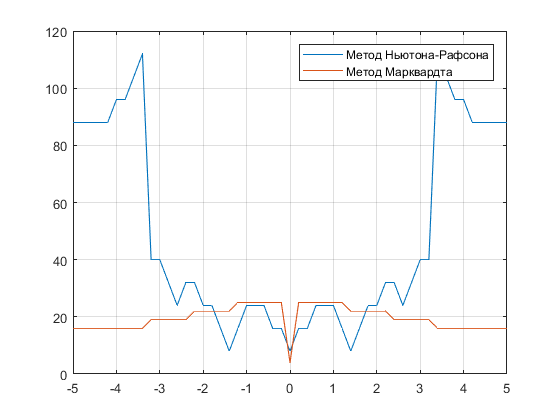

plot(x0,n)
hold on
plot(x0,nc)
grid on
legend({'Метод Ньютона-Рафсона','Метод Марквардта'})

Метод Ньютона-Рафсона сходится при -2.8<x<2.8

Метод Марквардта сходится на всём исследуемом интервале.

**6. Составить программу нахождения глобального минимума многомодальной функций методом перебора и методом ломаных. Построить графики, сделать выводы.**


$$f\left(x\right)=\frac{\mathrm{cos}\left(x\right)}{x^2 }$$



$$f\left(x\right)=\frac{1}{10}x+2\mathrm{sin}\left(4x\right)$$


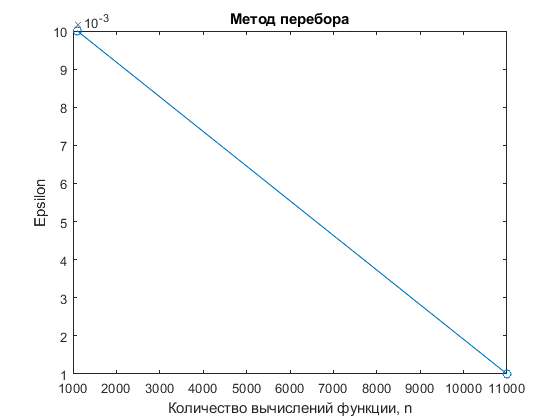

clc
clear
clf
f1 = @(x)cos(x)/x^2;
f2 = @(x)0.1*x+2*sin(4*x);
format long
eps1 = [0.01 0.001 0.001]; % изменил последнюю точность
a1 = 1;
b1 = 12;
a2 = 0;
b2 = 4;
n3 = 1:length(eps1);
fmin3 = 1:length(eps1);
xmin3 = 1:length(eps1);
fmin4 = 1:length(eps1);
xmin4 = 1:length(eps1);
for i = 1:length(eps1)
    [fmin3(i), xmin3(i), n3(i)] = perebor(f1, a1, b1, eps1(i));
    [fmin4(i), xmin4(i), n4(i)] = perebor(f2, a2, b2, eps1(i));
end
% Строим график eps против n
plot(n3, eps1, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод перебора');
hold off

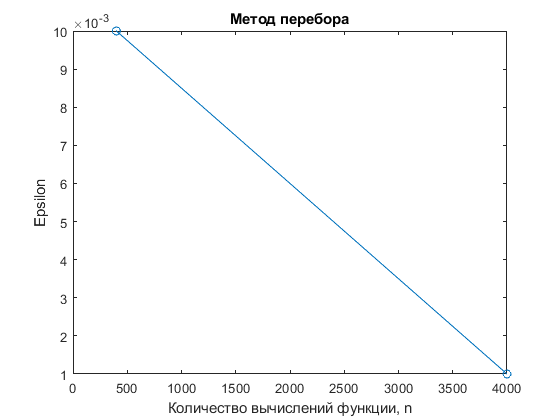

plot(n4, eps1, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод перебора');
hold off

eps2 = [0.1 0.001 0.00001]

eps2 =    0.100000000000000   0.001000000000000   0.000010000000000


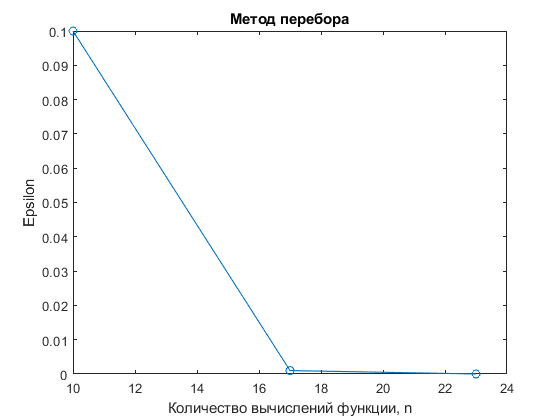

n5 = 1:length(eps2);
fmin5 = 1:length(eps2);
xmin5 = 1:length(eps2);
fmin6 = 1:length(eps2);
xmin6 = 1:length(eps2);
for i = 1:length(eps2)
    [fmin5(i), xmin5(i), n5(i)] = broken_lines_method(f1, a1, b1, eps2(i));
    [fmin6(i), xmin6(i), n6(i)] = broken_lines_method(f2, a2, b2, eps2(i));
end
% Строим график eps против n
plot(n5, eps2, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод перебора');
hold off

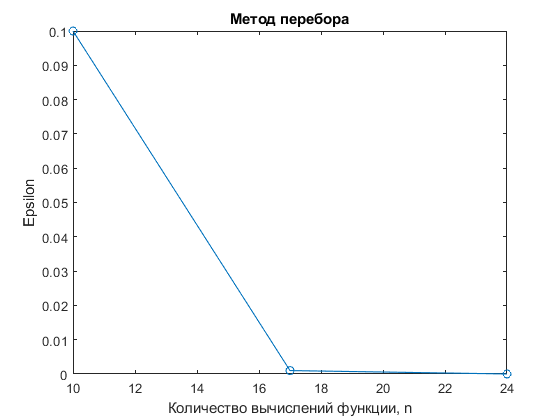

plot(n6, eps2, '-o'); % '-o' добавляет маркеры для удобства
xlabel('Количество вычислений функции, n');
ylabel('Epsilon');
title('Метод перебора');
hold off
x1 = 1:.1:12;
y1 = cos(x1)./x1.^2;
x2 = 0:.1:4;
y2 = 0.1.*x2 + 2.*sin(4.*x2);
hold off

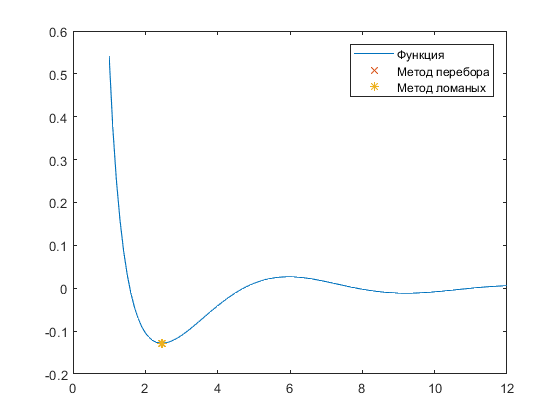

plot(x1,y1)
hold on
plot(xmin3,fmin3,'x')
plot(xmin5,fmin5,'*')
legend({'Функция','Метод перебора','Метод ломаных'})
hold off

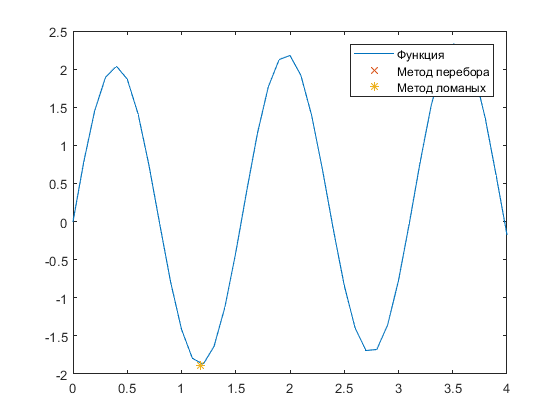

plot(x2,y2)
hold on
plot(xmin4,fmin4,'x')
plot(xmin6,fmin6,'*')
legend({'Функция','Метод перебора','Метод ломаных'})